# Estimation Theory

## Simple Design

Here we are just implementing the position estimation example from 3_kf_position in MATLAB to practice the change of syntax.

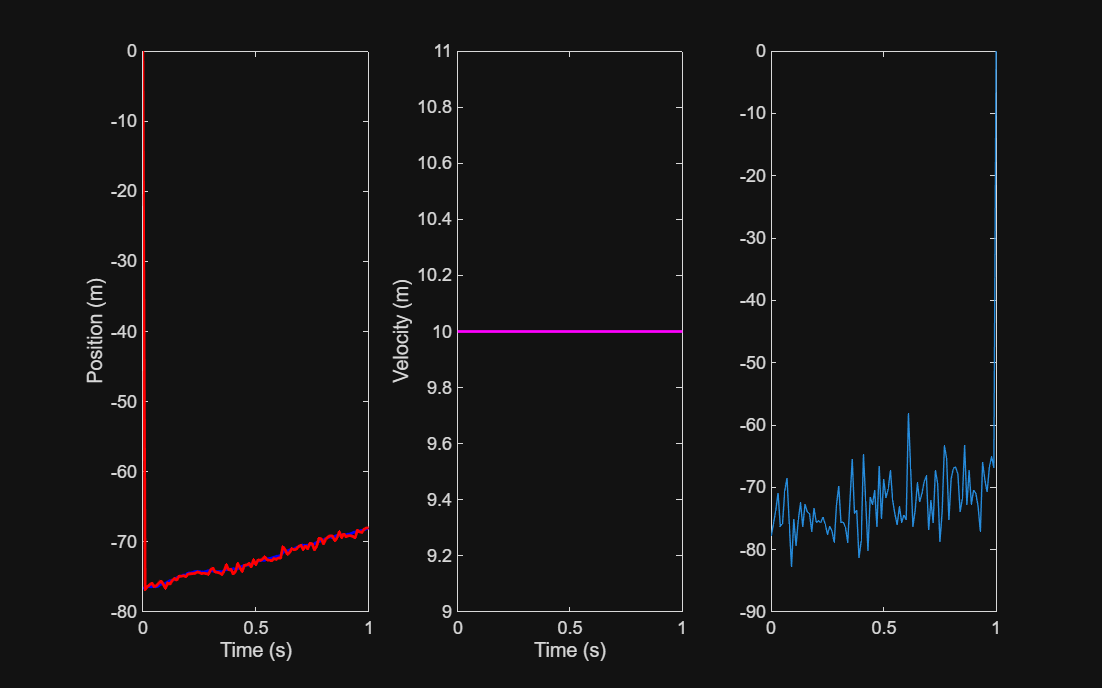

fs = 100;
h = 1 / fs;

A = [1 h;
     0 1];

G = [h; 0];

C = [1 0];

P0 = [1000 0;
      0 0];

xEst = [0; 10];

Q = 100;
R = 15;

mu = 0;
sigma = 1.5;


position = zeros(2, 101);
velocity = zeros(1, 101);
xEstVector = zeros(2, 101);

position(:, 1) = mvnrnd(xEst, P0);
xEstVector(:, 1) = xEst;

for t = 1 : 100
    
    noise = normrnd(0, sqrt(R), 1);
    velocity(t) = C * position(:, t) + noise;

    [sigma_mu, x_mu] = measurementUpdate(sigma, position(:, t), velocity(t), C, R);
    xEst(:, t + 1) = x_mu;

    [sigma_tu, x_tu] = timeUpdate(sigma_mu, x_mu, A, Q, G);

    measNoise = normrnd(0, sqrt(Q), 1)';

    position(:, t + 1) = A * position(:, t) + G * measNoise;

end

timeVector = (0 : 100) * (1 / fs);

f = figure;
f.Position = [0 0 800, 500];
tiledlayout(1, 3)
nexttile
plot(timeVector, position(1, :), 'b', 'LineWidth', 1.4, 'DisplayName', 'True state (position)')
hold on
plot(timeVector, xEst(1, :), 'r', 'LineWidth', 1.4, 'DisplayName', 'Estimated state (position)')
xlabel('Time (s)')
ylabel('Position (m)')

nexttile
plot(timeVector, position(2, :), 'g', 'LineWidth', 1.4, 'DisplayName', 'True state (velocity)')
hold on
plot(timeVector, xEst(2, :), 'm', 'LineWidth', 1.4, 'DisplayName', 'Estimated state (velocity)')
xlabel('Time (s)')
ylabel('Velocity (m)')

nexttile
plot(timeVector, velocity)

## Subfunctions

function [sigma, x] = measurementUpdate(sigma, x, y, C, R)
    z = C * sigma * C' + R;
    x = x + sigma * C' * linsolve(z, y - C * x);
    sigma = sigma - sigma * C' * linsolve(z, C * sigma);
end

function [sigma, x] = timeUpdate(sigma, x, A, Q, G)
    x = A * x;
    sigma = A * sigma * A' + Q * (G * G');
end